Clase Serie de Tiempo

semana 04: 12-09-2025

Graficos II

close all
clear all

% Directorrio de datos
%addpath C:/Users/Yzula Tec/OneDrive - Universidad de Concepción/Semestre III/series_tiempo

%Cargar datos
load datos_mareas_tortel_2020.mat

%mostrar datos
disp(datos_marea)

   1.0e+05 *

    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000
    7.3633    0.0000


whos("datos_marea")

  Name                 Size              Bytes  Class     Attributes

  datos_marea      96960x2             1551360  double              



Definir variables

time=datos_marea(:,1)

time = 1.0e+05 *

    7.3633
    7.3633
    7.3633
    7.3633
    7.3633
    7.3633
    7.3633
    7.3633
    7.3633
    7.3633


marea=datos_marea(:,2)

marea =     0.9859
    1.1653
    1.3572
    1.5192
    1.6249
    1.6469
    1.5630
    1.3908
    1.1916
    1.0088


Graficar

plot(time,marea)
title('Datos de marea de Tortel')
xlabel('time (s)')
ylabel('Altura de marea (m)')
datetick('x','m-yy')%convertir el formato de la fecha, puede variar ('mm-yyyy')
%en vez de colocar el nombre de variable, se escribe 'x'

En caso de plotear y no saber las variables

%plot(datos_marea(:,1),datos_marea(:,2))

El primer dato del tiempo

time(1)

ans = 736329

Convertir el dato a gregoriano

datevec(time(1))

ans =         2015          12          31           0           0           0


Toda la data

datevec(time)

ans =         2015          12          31           0           0           0
        2015          12          31           1           0           0
        2015          12          31           2           0           0
        2015          12          31           3           0           0
        2015          12          31           4           0           0
        2015          12          31           5           0           0
        2015          12          31           6           0           0
        2015          12          31           7           0           0
        2015          12          31           8           0           0
        2015          12          31           9           0           0


Guardar un año de datos

4*365*24+24

ans = 35064

datevec(time(35064))

ans =         2019          12          24          23           0           0


7*24+1

ans = 169

035064+169

ans = 35233

datevec(time(35233))

ans =         2020           1           1           0           0           0


366*24 + 24

ans = 8808

35233+8808

ans = 44041

datevec(time(44041))

ans =         2020          12          31           0           0           0


44041+23

ans = 44064

datevec(time(44064))

ans =         2020          12          31          23           0           0




%data_2020=datos_marea(2020,:)

Profesor

ini=(4*365*24)+(7*28-3);
fin=ini+366*24;
tiempo_2020=time(ini:fin);
marea_2020=marea(ini:fin);
save datos_mareas_tortel_nuevo.mat marea_2020 tiempo_2020

limpiar

clear all
close all

Cargar la nueva data

load datos_mareas_tortel_nuevo.mat

plotear

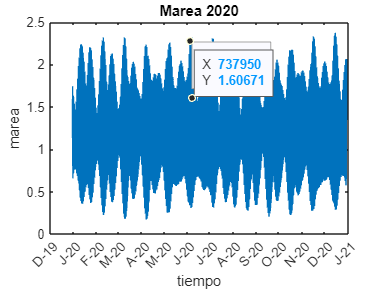

plot(tiempo_2020,marea_2020)
title('Marea 2020')
xlabel('tiempo')
ylabel('marea')

datetick('x','m-yy')